# A tutorial on how to use the Brain Observatory Toolbox

This tutorial will show you how to access the Brain Observatory data using MATLAB. In particular, this tutorial will show you how to:

1) Download meta information from brain observatory api and save it as MATLAB datatype

2) Build a brain_observatory_cache object to:

    A) Get general information on the brain observatory data

    B) Filter sessions by specified criteria in different aspects such as brain areas, imaging depth and stimuli type

    C) Download NWB files of filtered sessions

3) Extract imaging data from NWB files to:

    a) Get and plot fluorescence traces

    b) Convert fluorescence trace into data that is in "raster format" for further analysis

## Organization of the Brain Observatory Data

Before we start, we first want to describe the organization of the Brain Observatory Data. 

An *experiment container* contains three *sessions* (also called *experiments* or *ophys_experiments*) where recordings were made on a singe mouse, in a single brain region and at a particular imaging depth. Each of these three sessions consists of a series of "subexperiments" where a particular stimulus set was shown. NWB files downloaded from the Allen Institute API each consist of data from a single session. As described below, all data that we extract into "raster format" consists of data from a single "subexperiment" where a particular stimulus set was shown. 

Note: within an experiment container the same stimuli might be repeated in different sessions (i.e., different sessions can have the same "subexperiment type").  For example, Natural Movie 1 is shown in all three sessions in an experiment container. For more information see: [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

## 1) Download meta information from brain observatory api and save it as MATLAB datatype

To begin, set up the path to Brain Observatory Toolbox:

bot_dir_name = 'Brain-Observatory-Toolbox/';

Then, add it to MATAB's search path

addpath(bot_dir_name)

Next we will download the meta information which is stored in manifest files on the Allen API.  We can do this using the function get_manifests_info_from_api(). This function creates a MATLAB structure array with three tables and saves this structure array in a file called manifests.mat. Manifests.mat will be taken by the brain_observatory_cache as shown in the following section.

get_manifests_info_from_api()

Elapsed time is 0.000814 seconds.


load('manifests')

There are three tables in manifest.mat: container_manifest contains metadata of all experiment containers (m containers by n aspects of meta data), session_manifest contains metedata of all sessions (m sessions by n aspects of meta data), and cell_id_mapping contains mapping between new cell ids and the old cell id of all cells (m cells by number of ids).

As quoted from AllenSDK 's release note (0.13.2): "The cross-session alignment algorithm has been updated and re-run, so all cell specimen IDs have changed".

## 2) Build a brain_observatory_cache object

Brain_observatory_cache is a class that resembels BrainObservatoryCache in allensdk ([https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py](https://github.com/AllenInstitute/AllenSDK/blob/master/allensdk/core/brain_observatory_cache.py)).

It takes manifests and helps you fanthom and access Brain Observatory Data through three stages:

Stage A, it returns general information on the brain observatory data  from different aspects through correpsonding methods whose names all start with "get_" ;

Stage B, it filters sessions by different criteria through correpsonding methods with generic name pattern "filter_...by_...";

Stage C, it downloads NWB file(s) of filtered session(s) through the method named "download_nwb".

To beign, build a brain_observatory_cache_object

boc = brain_observatory_cache(manifests)

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [597×14 table]
                   stimuli: {1×17 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [597×1 double]
              session_type: {4×1 cell}


As you can see here, manifests.mat is stored in property manifets, table session_manifest from manifest.mat is stored in property session_table, and table container_manifest from manifest.mat is stored in property container_table.

The other properties will shine more light during the Stage B: filtering sessions; I will explain them then.

## 2A) Get general information on the brain observatory data

We implemented several methods whose names all start with "get_" to summairze the brain observatory data  from different aspects.

Here shown total number of containers

boc.get_total_num_of_containers()

ans = 199

Note: Total number of sessions should be whatever this returns * 3

Here shown all cortical depths that were ever recorded in any experiment container

boc.get_all_imaging_depths()

ans =    175
   265
   275
   300
   320
   325
   335
   350
   365
   375


Notet: Recording didn't take place equally among these depths, only popular depths are shown on homepage of Brain Observatory: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

Here shown all type of cre driver lines of all mice participated

boc.get_all_cre_lines()

ans = 6×1 cell array
    'Cux2-CreERT2'
    'Emx1-IRES-Cre'
    'Nr5a1-Cre'
    'Rbp4-Cre_KL100'
    'Rorb-IRES2-Cre'
    'Scnn1a-Tg3-Cre'


Note: All mice had the same reporter line: Ai93 and tTA driver line: Camk2a-tTA

For more information about transgenic lines: [http://observatory.brain-map.org/visualcoding/transgenic](http://all mice had the same reporter line: Ai93 and driver line: Camk2a-tTA; there were several cre lines as shown here. % for more information about transgenic lines: http://observatory.brain-map.org/visualcoding/transgenic)

Here shown all brain regions that were ever recorded in any experiment container

boc.get_all_targeted_structures()

ans = 6×1 cell array
    'VISal'
    'VISam'
    'VISl'
    'VISp'
    'VISpm'
    'VISrl'


For their locations, see homepage of Brain Observatoy: [http://observatory.brain-map.org/visualcoding](http://observatory.brain-map.org/visualcoding)

Here shown all types of sessions that ever appeared in any experiment container

boc.get_all_session_types()

ans = 4×1 cell array
    'three_session_A'
    'three_session_B'
    'three_session_C'
    'three_session_C2'


Note: There are always three sessions in each container: session A, session B,  and session C or session C2

Here shown all type of stimuli that were ever used in any of the four types of sessions

boc.get_all_stimuli()

ans = 9×1 cell array
    'drifting_gratings'
    'locally_sparse_noise_eight_degree'
    'locally_sparse_noise_four_degree'
    'natural_movie_one'
    'natural_movie_three'
    'natural_movie_two'
    'natural_scene'
    'spontaneous_activity'
    'static_gratings'


Note: For mapping between session type and stimulus type, see [http://alleninstitute.github.io/AllenSDK/brain_observatory.html](http://alleninstitute.github.io/AllenSDK/brain_observatory.html)

Here shown the numer of experiment containers recorded in each brain region


boc.get_summary_of_containers_along_targeted_structures()

     VISal      33 
     VISam      25 
     VISl       36 
     VISp       54 
     VISpm      35 
     VISrl      16 


Here shown the numer of experiment containers recorded at each cortical depth

boc.get_summary_of_containers_along_imaging_depths()

     175      50 
     265       1 
     275      72 
     300       4 
     320       1 
     325       3 
     335       3 
     350      33 
     365       1 
     375      30 
     435       1 


Here shown the number of experiment containers recorded at each cortical depth in each brain region

boc.get_summary_of_containers_along_depths_and_structures()

ans = 12×7 table
             VISal    VISam    VISl    VISp    VISpm    VISrl    total
             _____    _____    ____    ____    _____    _____    _____

    175       8        5       10      11      11        5        50  
    265       1        0        0       0       0        0         1  
    275      12        9       15      20      11        5        72  
    300       1        0        1       1       1        0         4  
    320       0        1        0       0       0        0         1  
    325       0        1        1       0       1        0         3  
    335       0        0        0       2       1        

## 2B) Filter sessions by specified criteria in different aspects such as brain areas, imaging depth and stimuli type

Now we proceed to Stage B: filtering sesssions. 

Build a new  "clean" brain_observatory_cache object first and I will explain right after.

boc = brain_observatory_cache(manifests)    

boc =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [597×14 table]
                   stimuli: {9×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [597×1 double]
              session_type: {4×1 cell}


To review, manifests.mat is taken in by  brain_observatory_cache and stored in property "manifets", the manifest of all sessions (m sessions by n aspects of meta data) from manifest.mat is stored in property "session_table", and the manifest of all containers (m containers by n aspects of meta data) from manifest.mat is stored in property "container_table".

We implemented several methods with generic name pattern "filter_...by_..." to filter sessions by criteria in different aspects. As methods get called, property filtered_session_table, which started with the same content as session_table, gets eliminated to meet new criteria, and then other properties that each summarize the meta data of all filtered sesssions stored in "fitered_session_table" from a different aspect ("meta meta data") get updated. When a brain_observatory_cache object is constructed, the "meta meta data" is simply the "meta meta data" of  all sessions.

Here we show an example of searching for sessions that primary visual cortex was  recorded at 275 mm deep and during which drifting gratings were shown.

Eliminate all sessions to sessions that only showed drifting gratings

boc.filter_sessions_by_stimuli('drifting_gratings')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [199×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {6×1 cell}
             imaging_depth: [11×1 double]
              container_id: [199×1 double]
                session_id: [199×1 double]
              session_type: {'three_session_A'}


Note the changes of all properties except the first top three.

Eliminate current filtered sessions to sessions that have posterior Primary Visual Cortex recoreded

boc.filter_sessions_by_targeted_structure('VISp')

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [54×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: [6×1 double]
              container_id: [54×1 double]
                session_id: [54×1 double]
              session_type: {'three_session_A'}


Eliminate current filtered sessions to sessions that were recoreded at 275 mm deep

boc.filter_sessions_by_imaging_depth(275)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [20×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: {'VISp'}
             imaging_depth: 275
              container_id: [20×1 double]
                session_id: [20×1 double]
              session_type: {'three_session_A'}


As we can see now, there are 20 sessions that met all of the criteria given. 

Let's just get one random session out of the 20 sessions, so we don't wait forever when I show you how to download real data at the next stage

boc.filter_sessions_by_container_id(527550471)

ans =   brain_observatory_cache with properties:

             session_table: [597×14 table]
           container_table: [199×13 table]
                 manifests: [1×1 struct]
    filtered_session_table: [1×14 table]
                   stimuli: {4×1 cell}
        targeted_structure: 'VISp'
             imaging_depth: 275
              container_id: 527550471
                session_id: 527745328
              session_type: {'three_session_A'}


Take a look at metedata of the final filtered session to convince you how friendly my property list ("meta meta data") is

boc.filtered_session_table

ans = 1×14 table
     date_of_acquisition      experiment_container_id    fail_eye_tracking        id        imaging_depth              name              specimen_id      stimulus_name                                    storage_directory                                   targeted_structure_id    experiment_container    well_known_files    targeted_structure      specimen  
    ______________________    _______________________    _________________    __________    _____________    ________________________    ___________    _________________    _____________________________________________________________________

Hint: In future days, when you get lots NWB files downloaded and you lose track of who the heck they are, you can use brain_observatory_cache to look up their meta data and "meta meta data".

## 2C) Download NWB files of filtered session(s)

Finally comes to Stage C: downading real data stored in NWB files

For more info about NWB,

    See its github page: [http://neurodatawithoutborders.github.io/](http://neurodatawithoutborders.github.io/)

    See its publication: [http://www.sciencedirect.com/science/article/pii/S0896627315009198](http://www.sciencedirect.com/science/article/pii/S0896627315009198)

First, set up the path to NWB directory.

nwb_dir_name = [bot_dir_name,'nwb_files/'];

Then, call the method named "download_nwb" to dowload all NWB file(s) corresponding to filtered session(s) stored in brain_observatory_cache and save it under your NWB directory.

boc.download_nwb(nwb_dir_name);

desired nwb file already exists

Note: The size of a nwb file is at the scale of 100 MB, so you definielty want to move around instead of sitting here and waiting. Once brain_observatory_cache gets the file downloaded, it will spit you a message, so no worries.

## 3) Import imaging data from nwb files

Now we have acquired an NWB file, we can extract the florescence traces from the NWB file and convert them to data in "raster format" (n trials by  t times for every cell), which is easier to analyze.

For more info about raster format, see [http://www.readout.info/toolbox-design/data-formats/raster-format/](http://www.readout.info/toolbox-design/data-formats/raster-format/)

To start, add the NWB file to MATLAB searching path.

% add path to nwb files
addpath([bot_dir_name, 'nwb_files/'])

## 3a) Get and plot fluorescence traces

Before we start converting data format, you might just want to plot some fluorescence traces to make sure they look normal or for fun.

To do this you can either

     i) get fluorescence traces of all cells in one session and plot them in your own way or

     ii) use the built-in plot function to plot fluorescence traces of  one cell in one session 

Here we show an example of i):

    Extract and compute all four types fluorescence traces available in the NWB file of session 517745328 and save them to the worksapce.

session_id  = 527745328;
[raw,demixed,neuropil_corrected,DfOverF] = save_fluorescence_traces(session_id);

Elapsed time is 4.392045 seconds.


Note: each type of trace was stored as h5read table (k dimensions of cells by t dimesions of times) and saved as n dimesions of sampling points by k dimensions of cells matlab matrix

Alternatively, this is an example of ii):

     Plot fluorescence traces of a random cell 529022196 in session 527745328 directly

Caution: "plot_fluorecence_traces" takes one new cell id 

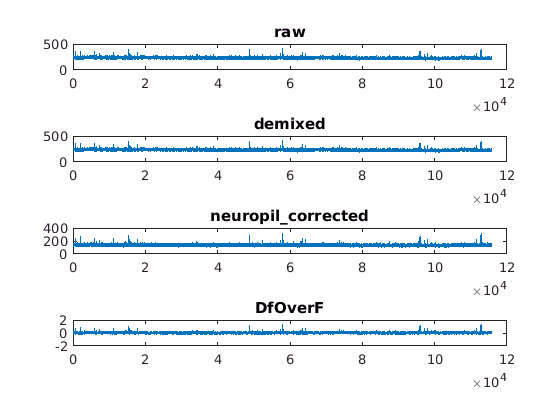

session_id  = 527745328;
cell_id = 529022196;
plot_fluorecence_traces(session_id,cell_id);

## 3b) Convert fluorescence trace into data in "raster format" 

To start, set up the path to raster directory 

raster_dir_name = [bot_dir_name, 'raster/'];

Tell the "convert" function the session you are working on, the type of stimuli you are interested in, and the type of fluorescence trace you want to use, and then set it off. 

session_id  = 527745328;
stimuli = 'drifting_gratings';
fluorescence_trace = 'DfOverF';

current_raster_dir_name = convert_fluorescenece_trace_into_raster_format(fluorescence_trace,...
    session_id, stimuli,raster_dir_name);

Brain-Observatory-Toolbox/raster/drifting_gratings_527745328/ already exists

Note: This doesn't take long.

## 4) Get Masks...